Creating a 2D zonotope using the zono class.

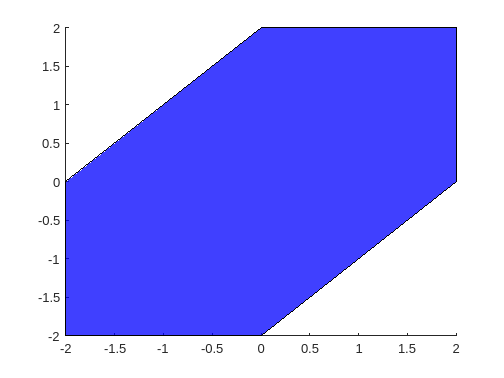

G = [1 0 1;0 1 1]; % Generator matrix with 3 generators
c = zeros(2,1);
Z = zono(G,c);
figure(1)
Z.plot('b',0.75)

Creating a constrained zonotope and checking emptiness and point containment

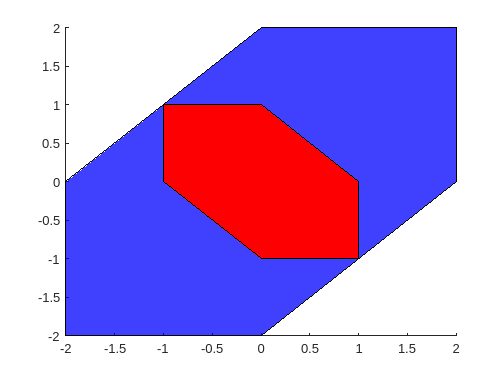

G = [1 0 1;0 1 1]; % Generator matrix with 3 generators
c = zeros(2,1);
A = [1 1 1];
b = [0];
cZ = conZono(G,c,A,b);
figure(2)
cZ.plot('r',0.75)

cZ.checkEmpty()

Solving problem using linprog.

Optimal solution found.



ans = logical
   0


cZ.checkPointContain([0;0])

Solving problem using linprog.

Optimal solution found.



ans = logical
   1


cZ.checkPointContain([1;1])

Solving problem using linprog.

No feasible solution found.

Linprog stopped because no point satisfies the constraints.



ans = logical
   0



cZ.b = 20;
cZ.checkEmpty()

Solving problem using linprog.

No feasible solution found.

Linprog stopped because no point satisfies the constraints.



ans = logical
   1


cZ.plot('g',0.75)

Unrecognized field name "x".

Error in solveLP (line 51)
        x = result.x;

Error in conZono/plotConZono2D (line 28)
[x,~,~] = solveLP(dir*obj.G,[],[],Aeq,beq,lb,ub,optSolver);

Error in abstractZono/plot (